# Modeling and Optimizing a Battery Charging Profile

In this script, we will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

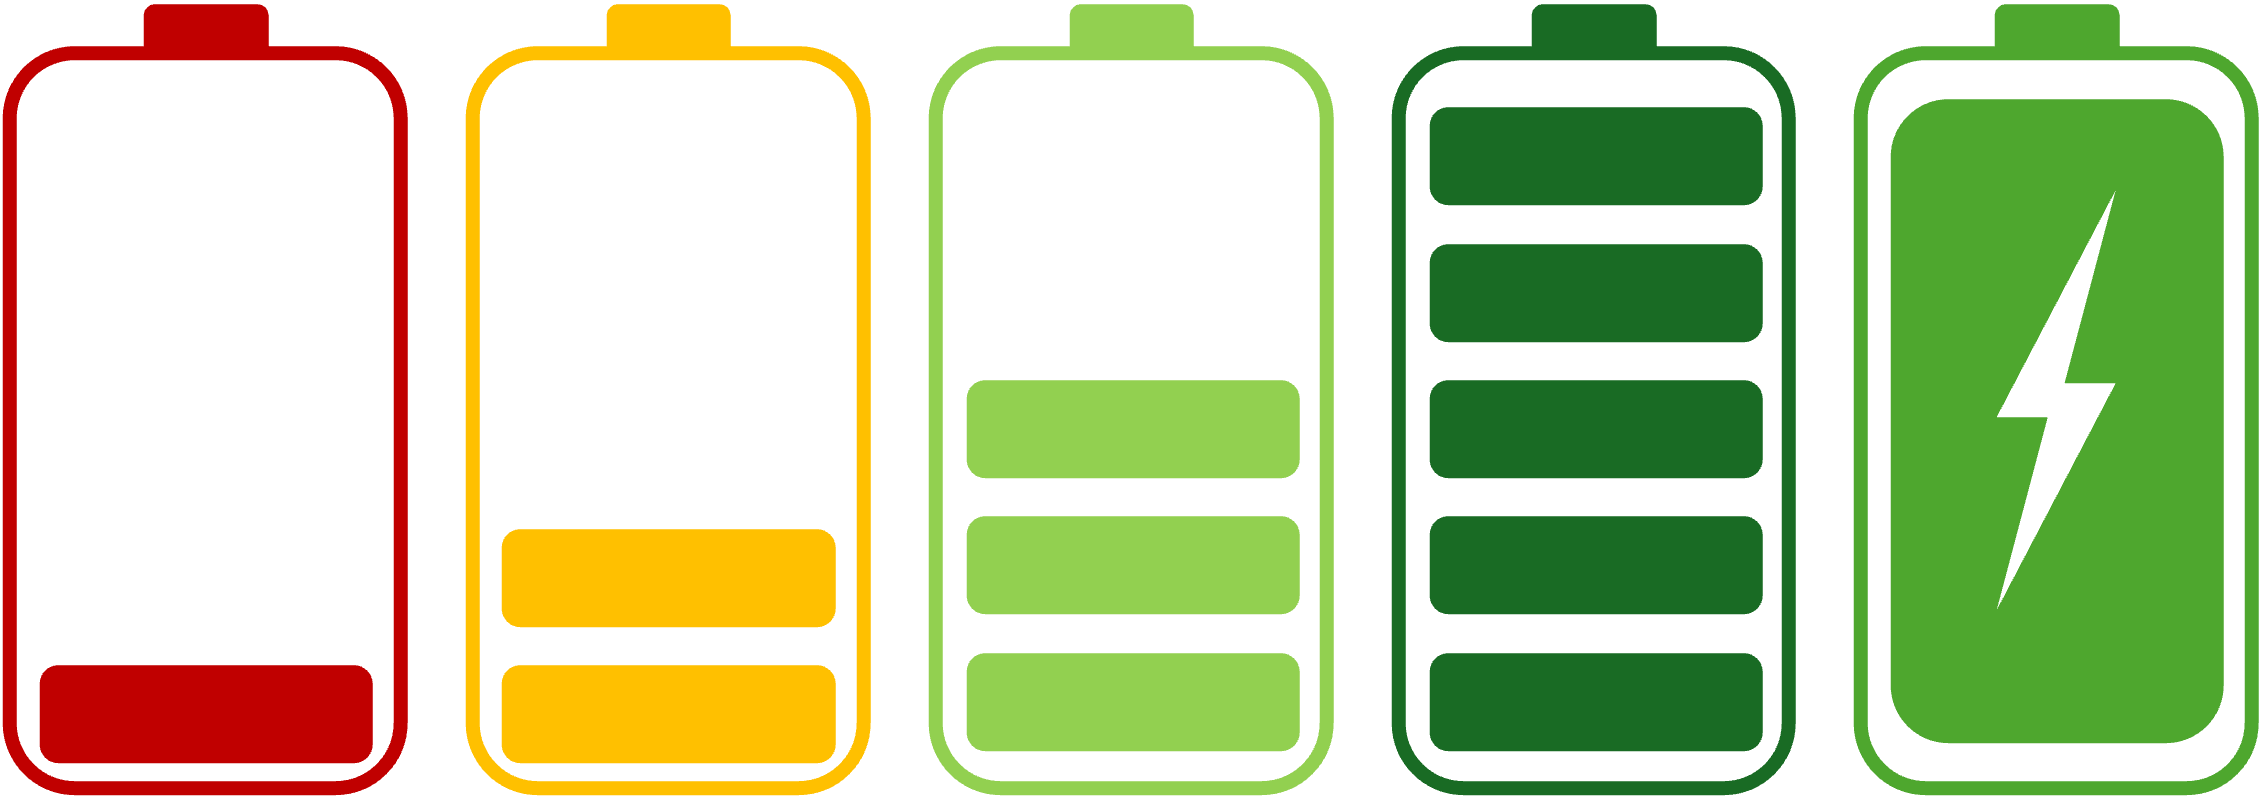

## Break Down the Problem

**Problem Statement:**

Model and analyze the charging profile of a lithium-ion battery using real-world data. We need to use MATLAB to mathematically fit a specific voltage equation to the provided battery data, visualize the electrical characteristics over time, and apply numerical methods (integration and differentiation) to compute key performance metrics like total energy transfer, charging rates, time-to-charge, and efficiency losses due to resistance.

**List the requirements, constraints, and success criteria for the project:**

- **Requirements:**

- Must use MATLAB to perform all calculations and modeling.

- Fit the given voltage equation to the provided lithium-ion battery data.

- Generate three specific plots: voltage vs. time, current vs. time, and power vs. time.

- Use numerical integration to compute total energy delivered (area under the power-time curve).

- Calculate derivatives to analyze the rate of voltage change across different charging intervals.

- Determine the exact time it takes to reach 80% and 100% charge states.

- Compute the energy lost due to internal resistance.

- **Constraints:**

- The model must be built upon the specific dataset and voltage equation provided in the broader Project Description.

- Calculations for energy and rates of change must rely on numerical methods applied to the provided discrete data points.

- **Success Criteria:**

- A MATLAB script that successfully runs without errors and performs the necessary curve fitting.

- Clear, accurately labeled plots for voltage, current, and power over time.

- Accurate final computed values for total energy delivered, time to 80%/100% charge, and energy loss.

**What is your proposed solution?**

The proposed methodology involves the development of a structured MATLAB Live Script to systematically analyze the empirical battery dataset. Initially, the time-series data will be imported into the MATLAB workspace, and the Curve Fitting Toolbox will be utilized to model the theoretical RC-circuit voltage equation against the experimental charging data. Following the curve fit, an instantaneous power array will be derived by computing the product of the voltage and current vectors at each discrete time interval.

To evaluate the battery's performance characteristics, visual representations of the voltage, current, and power profiles will be generated. Subsequently, numerical methods will be applied to extract key metrics: trapezoidal numerical integration (`trapz`) will be employed on the power array to quantify the total energy transfer, while numerical differentiation (`diff`) will be utilized to determine the instantaneous rate of voltage change across distinct charging phases. These computational techniques will facilitate the precise determination of time-to-charge thresholds (80% and 100%) and the quantification of energy dissipation attributed to internal resistance.

**List the steps you will need to take to achieve your proposed solution:**

- **Data Import & Setup:** Load the real lithium-ion battery data into MATLAB workspace variables (extracting time, voltage, and current).

- **Curve Fitting (Task 1):** Define the provided voltage equation and fit it to the real data using MATLAB's regression/curve-fitting functions.

- **Data Calculation:** Compute the electrical power at each time step (Power = Voltage * Current).

- **Visualization (Task 2):** Create a figure with subplots for voltage vs. time, current vs. time, and power vs. time.

- **Integration (Task 3):** Apply numerical integration (e.g., trapezoidal rule) on the power-time data to calculate the total energy delivered.

- **Differentiation (Task 4):** Calculate the derivative of the voltage data with respect to time (dV/dt) to analyze the charge rate at different intervals.

- **Threshold Analysis:** Analyze the data arrays to find the timestamps corresponding to 80% and 100% charge levels.

- **Efficiency Calculation:** Calculate the energy lost to resistance using the current data and the assumed internal resistance values.

**What challenges do you face in the process of achieving the solution?**

- **Data Noise:** Real battery data often contains noise or fluctuations. Fitting a clean mathematical equation to noisy data might require preprocessing or choosing the right fitting tolerances.

- **Numerical Errors:** Numerical integration and differentiation can introduce errors depending on the time-step size of the provided data. Large time gaps between data points could make the derivatives spike unnaturally or make the total energy calculation less accurate.

- **Identifying Charge States:** Accurately determining exactly when the battery hits 80% and 100% charge might be tricky if the data points don't land exactly on those percentages, requiring interpolation.

## Task 1: Fit the voltage equation to a lithium-ion battery profile

**1.1  Objective and success criteria**

Task 1 fits the prescribed first-order RC law to a single measured charge cycle in order to estimate the charging time constant and to establish how far a single-exponential model can represent this cell, which is charged with a multi-step constant-current, constant-voltage (CC-CV) profile rather than from a fixed source voltage. The inputs are elapsed time, terminal voltage and current for one cycle of the MathWorks single-cell lifetime dataset, plus one externally known constant: the 3.6 V full-charge voltage. The outputs are the fitted model, one labelled figure of measurement against model, and the printed goodness-of-fit statistics. Task 1 is complete when:

- the section runs from a cleared workspace and regenerates the figure and the statistics;

- the fit converges to a finite, strictly positive time constant inside the bounds, reported with its 95% confidence interval and the full goodness-of-fit statistics;

- the agreement between the fitted exponential and the measured profile is assessed quantitatively, and each systematic departure is attributed to a specific phase of the CC-CV charging protocol.

**1.2  Where the voltage equation comes from**

The equation is the exact solution of the circuit the cell is modeled as, not a curve chosen because it resembles the data. The charger is treated as a constant voltage source, the ohmic losses of electrolyte, electrodes and connections are lumped into one series resistance, and the charge storage of the cell into one capacitance. Kirchhoff's voltage law around that loop gives $V_{\max } =i\left(t\right)R+V\left(t\right)$, and the current is the rate at which charge reaches the capacitance, $i\left(t\right)=C\frac{dV}{dt}$. Substituting gives a first-order linear ODE,


$$\mathrm{RC}\frac{dV}{dt}+V\left(t\right)=V_{\max }$$


which, separated and integrated with the capacitance initially uncharged, yields the equation to be fitted:


$$V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$$


Physically, the full source voltage stands across the resistance at the start, so charging is fastest then; as the capacitance charges it develops an opposing voltage, leaving only the remaining gap to drive current. The rate of charging is proportional to how much charging is left to do, and that is precisely the condition that produces an exponential rather than any other saturating curve.

The product $\tau =\mathrm{RC}$ is the only time scale present, and it must be a time because the exponent is dimensionless: an ohm is a volt per ampere and a farad a coulomb per volt, so their product is a coulomb per ampere, a second. It is the time to close 63.2% of the gap to the final voltage, and because each interval of one time constant removes the same fraction of whatever gap remains, charging is 99.3% complete after five of them.

**1.3  Parameter Choice & RC omission **

The maximum voltage is fixed at 3.6 V rather than fitted. It is externally known, and fitting an asymptote and a time constant together makes both less certain because they trade off against each other over a record only a few time constants long. In the code it is declared a problem parameter, the Curve Fitting Toolbox term for a value supplied rather than optimized. The resistance and capacitance are not estimated separately because they cannot be: they enter the model only through their product, so voltage data cannot distinguish a large resistance with a small capacitance from the reverse. This is parameter identifiability, not a numerical limitation, and no optimizer resolves it. Only the lumped time constant is estimated, in seconds; if the elements are wanted, the dataset's internal-resistance column gives $C=\tau /R$ afterwards, which is an inference from a second measurement rather than an output of this fit.

**1.4  Why We Use Nonlinear Square Method**

The model is linear in the maximum voltage but nonlinear in the time constant, which sits inside an exponential in a denominator. Its derivative with respect to that parameter still depends on the parameter, so the least-squares condition does not reduce to linear normal equations and there is no closed-form solution. The residual sum of squares


$$S\left(\tau \right)=\sum_{i=1}^N {\left(V_i -V_{\max } \left(1-e^{-\frac{t_i }{\tau }} \right)\right)}^2$$


must therefore be minimized iteratively, which is what nonlinear least squares does, by default with a trust-region reflective algorithm well suited to a bounded problem. It is also the only admissible choice here: the toolbox restricts linear least squares to models linear in their coefficients, so a custom exponential leaves no alternative.

The tempting shortcut was considered and rejected. Taking logarithms linearizes the model to


$$\ln \left(1-\frac{V}{V_{\max } }\right)=-\frac{t}{\tau }$$


so the time constant could come from the slope of an ordinary linear regression with no iteration. Three objections, in increasing order of seriousness: it minimizes a differently weighted objective than the additive, roughly constant-magnitude voltage noise justifies; it amplifies that noise severely near the asymptote, where most samples of a charge record lie; and it is undefined once any measured sample reaches the assumed maximum, which during a constant-voltage hold at 3.6 V is close to certain rather than a rare edge case. A polynomial or spline would track the data more closely but yields no time constant, so it could not serve as the benchmark Task 3 needs. Nonlinear least squares also accepts bounds, so the requirement that the time constant be positive is enforced rather than hoped for, and it supports a confidence interval on the estimate. Its one cost is dependence on the starting guess, which is why the appendix sweeps it.

**1.5  Implementation**

- **Select one cycle **on the cycle index, so that cell aging does not blend charge profiles recorded at different states of health into a single fit.

- **Keep the charging phase only, **selected on positive current. Two things are worth checking rather than assuming: that the sign convention is as expected, confirmed by the voltage rising across the window, and that the retained samples are contiguous, since a logical filter will silently join charge segments separated by rest periods.

- **Build the time axis **by subtracting the first timestamp and converting to seconds, which puts the origin where the model's initial condition assumes it.

- **Fit **with nonlinear least squares, a 500 s starting guess whose order of magnitude comes from the observed charge duration, and a lower bound just above zero enforcing a positive time constant; the maximum voltage is passed in as the problem parameter.

- **Report **measurement and model on one set of axes with units, then print the goodness-of-fit statistics and the fitted model so the time constant appears in the output.

**1.6  Assumptions and limitations**

- **One resistance and one capacitance. **Real cells relax on several time scales, so a single time constant is a summary rather than a complete description.

- **A constant-voltage source. **This cell is charged with a dynamic constant-current then constant-voltage profile. During the constant-current phase the voltage rises nearly linearly, so systematic disagreement there is expected and is a property of the model rather than a defect in the fit.

- **Zero initial voltage. **False for a battery, which retains a substantial open-circuit voltage when discharged. This is the largest source of bias: the model is pinned to the origin while the measurement starts near three volts, so the optimiser distorts the time constant to compensate.

- **Additive, roughly constant-magnitude voltage noise. **A fair description of voltmeter error, and the condition that makes least squares the appropriate estimator.

The third is imposed by the prescribed equation, not by any choice in the code, and it can be quantified rather than merely noted. Fitting the three-parameter variant


$$V\left(t\right)=V_0 +\left(V_{\max } -V_0 \right)\left(1-e^{-t/\tau } \right)$$


as a sensitivity test, while still reporting the prescribed model as the result, shows how much of the residual that single assumption accounts for. The appendix does this.

**1.7  Validation strategy**

R-squared alone is weak evidence, because any curve that rises and saturates scores well against data that rises and saturates. The checks in the appendix therefore triangulate: an independent hand estimate of the time constant from the 63.2% crossing, which validates the implementation but not the physics since it shares the zero-initial-voltage assumption; a 95% confidence interval, so the estimate is reported as an interval; a residual plot, where structure rather than scatter diagnoses a wrong functional form; a sweep of the starting guess across five decades to confirm the optimum is global rather than local; and explicit edge-case checks that the charge window is non-empty, strictly increasing, free of large gaps, and rising.

The expected outcome is worth stating in advance. Because the cell is charged with a CC-CV profile rather than from a fixed source voltage, the exponential should coincide with the measurement over the constant-voltage plateau and depart from it systematically over the constant-current stages. The residuals should therefore be structured rather than scattered, and the fitted time constant should be interpreted only after it has been checked against the observed duration of the charge.

%% Task 1: Modeling the Battery Charging Profile (First-Order RC Circuit)
% This script extracts the first charging cycle from a battery dataset, 
% fits the voltage data to a first-order RC exponential equation, 
% visualizes the fit, and outputs the goodness-of-fit statistics.

%% Step 1 & 2: Data Extraction and Pre-Processing
% Filter the main dataset to only include data from the first cycle.
cycle1Data = data(data.Cycle_Index == 1, :);

% Isolate the charging phase. 
% We know the battery is charging when the current is positive (> 0).
chargeData = cycle1Data(cycle1Data.Current > 0, :);

% Convert the DateTime timestamps into a numerical array of elapsed seconds.
% We subtract the very first timestamp from all others so our time starts at t = 0.
t_data = seconds(chargeData.DateTime - chargeData.DateTime(1));

% Extract the corresponding voltage readings for the y-axis.
V_data = chargeData.Voltage;

%% Step 3: Set Up the Mathematical Model
% Define the known maximum voltage for this specific lithium-ion battery.
Vmax_val = 3.6; 

% Configure the settings for the curve fitting algorithm.
% - 'Method': We use Nonlinear Least Squares since our equation is exponential.
% - 'StartPoint': An initial guess for 'tau' (the RC time constant) in seconds.
% - 'Lower': Sets a lower boundary so tau doesn't drop to physically impossible values (<= 0).
fo = fitoptions('Method', 'NonlinearLeastSquares', ...
                'StartPoint', 500, ...
                'Lower', 1e-5);

% Define the custom exponential equation: V(t) = Vmax * (1 - e^(-t/tau))
% - 'problem': Indicates Vmax is a known constant we will provide.
% - 'independent': Specifies 't' as our x-axis time variable.
% - 'options': Applies the algorithm rules we just set up above.
ft = fittype('Vmax * (1 - exp(-t/tau))', ...
             'problem', 'Vmax', ...
             'independent', 't', ...
             'options', fo);

% Execute the curve fit. 
% We pass in our time data, voltage data, the equation setup, and the actual Vmax value.
% 'chargeFit' stores the resulting equation; 'gof' stores the accuracy metrics.
[chargeFit, gof] = fit(t_data, V_data, ft, 'problem', Vmax_val);

%% Step 4: Visualize the Data and the Fitted Curve
figure; % Open a new, clean figure window

% Plot the actual raw data points and the smooth fitted curve together
plot(chargeFit, t_data, V_data);

% Add clean, professional labels and a title
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Battery Charging Profile Fit (Cycle 1)');

% Add a legend to differentiate the raw data from the model
legend('Actual Charge Data', 'Fitted RC Curve', 'Location', 'best');

%% Step 5: Display Analytical Results
% Print out the Goodness-of-Fit (GOF) statistics (like R-squared and RMSE)
% to prove the mathematical accuracy of our model.
disp('--- Goodness of Fit (GOF) Statistics ---');
disp(gof);

% Print the final fitted equation, which will reveal our estimated 
% value for 'tau' (the RC time constant).
disp('--- Fitted Equation and Estimated Tau ---');
disp(chargeFit);




**Figure 1. **Measured terminal voltage during the charging phase of cycle 1 (points) with the fitted first-order RC model (line). The measurement shows the three features of a multi-step CC-CV charge: a fast initial rise, constant-current stages separated by downward voltage steps near 300 s and 660 s, and a constant-voltage plateau at 3.6 V from about 1250 s onward. The fitted exponential reaches its 3.6 V asymptote within about one second, so it coincides with the plateau and lies above the constant-current stages.

**1.8  Conclusion**

**Results. **Fitting the prescribed equation to 612 samples of cycle 1, with the maximum voltage held at 3.6 V, returned a time constant of 0.228 s with a 95% confidence interval of 0.210 to 0.246 s. The goodness-of-fit statistics were a sum of squared errors of 45.63 over 611 residual degrees of freedom, R-squared of 0.229, adjusted R-squared of 0.229, and a root-mean-square error of 0.273 V. The model therefore accounts for 23% of the variance in the measured voltage, and the fit converged to a well-bounded parameter well inside the imposed lower limit.

**What the measurement shows. **The charge follows a multi-step CC-CV profile. The terminal voltage rises steeply from about 2.0 V to 3.4 V in the first few seconds, then climbs slowly through a series of constant-current stages. The downward steps of roughly 0.08 V near 300 s and 0.14 V near 660 s occur where the charging current is reduced between stages: the ohmic contribution to the terminal voltage falls immediately with the current, so the measured voltage steps down while the state of charge continues to increase. From about 1250 s the cell is held at a constant 3.6 V, and this constant-voltage plateau accounts for roughly the final third of the samples.

**How the model responds. **The fitted exponential has a single time scale, whereas the measurement contains three distinct regimes. With the asymptote fixed at 3.6 V and the curve constrained to pass through the origin, the time constant is determined almost entirely by the steep initial rise, and the model consequently saturates within about one second. It therefore reproduces the constant-voltage plateau exactly and lies between roughly 0.15 V and 0.2 V above the measurement throughout the constant-current stages. The 0.273 V root-mean-square error is this systematic offset rather than random scatter, and it exceeds the 0.2 V of voltage rise that occurs across the constant-current portion.

**Quantitative assessment. **A time constant of 0.228 s corresponds to 99% completion after five time constants, or about 1.1 s, whereas the measured charge occupies approximately 1900 s. The fitted parameter is therefore a description of the initial voltage step and not of the charge-transfer process. The confidence interval of plus or minus 8% is correspondingly narrow because the early samples determine that step precisely, but it quantifies precision within the assumed model only. Taken with the R-squared of 0.229, the model is quantitatively valid over the constant-voltage phase and quantitatively invalid over the constant-current phases.

**Conclusion. **A first-order RC analog is the exact solution for charging from a fixed source voltage, which corresponds to only one of the three regimes present in this record. The model reproduces the constant-voltage plateau and the initial ohmic step, and does not represent the constant-current stages, which is why the fitted time constant characterises the initial step rather than the full charge. The measured profile is described within 0.273 V by a single-exponential model whose valid range is the constant-voltage portion of a CC-CV charge.

## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

**2.1  Objective and success criteria**

Task 2 visualizes how energy moves through the cell by plotting the three electrical quantities that describe it, voltage, current and power, across one complete charge and discharge cycle, and then isolates the charging phase so that the model fitted in Task 1 can be laid over the data it was fitted to. The inputs are the time, voltage and current columns for cycle 1 of the MathWorks single-cell lifetime dataset. The outputs are one figure containing the three required subplots, a second figure comparing the measured charging voltage against the fitted RC curve, and a small table of the fit statistics. Task 2 is complete when:

- one figure contains the voltage, current and power subplots for cycle 1, each labeled with its quantity and SI unit on a common time axis;

- power is derived from the measured voltage and current rather than assumed, and its sign behaves consistently with the current across both the charging and discharging halves of the cycle;

- the charging phase is isolated and the fitted model overlaid on it, so that the region over which the model is valid can be read directly off the figure.

Task 2 also connects the other two tasks. It supplies the visual evidence for the CC-CV behavior that Task 1 concluded was responsible for the poor fit, and the power array it computes is the integrand for the energy calculation in Task 3, $E=\int_0^{t_f } P\left(t\right)dt$.

**2.2  The three quantities and how they relate**

Voltage and current are measured; power is derived. Each row of the dataset pairs a voltage and a current recorded at the same instant, so the element wise product


$$P\left(t\right)=V\left(t\right)i\left(t\right)$$


is the instantaneous electrical power, in watts, since one volt times one ampere is one watt. The dataset uses the convention that current into the cell is positive, which means power is positive while the cell is charging and negative while it is discharging. Plotting the whole cycle rather than the charging window alone makes that sign change visible, and the instant at which power crosses zero in the third subplot must coincide with the instant at which current crosses zero in the second. That correspondence is the reason the three quantities are shown together on a shared time axis instead of in isolation.

The terminal voltage is not the internal state of the cell. It is the open-circuit voltage plus the ohmic drop across the internal resistance,


$$V\left(t\right)=V_{\mathrm{oc}} \left(t\right)+i\left(t\right)R$$


so terminal voltage responds instantly to a change in current even though the state of charge cannot change instantly. This explains a feature that looks anomalous in the Task 1 figure: wherever the charger steps the current down between stages, the ohmic term shrinks immediately and the measured voltage steps down with it, while the cell in fact continues to charge. Only the current subplot makes that interpretation available, which is why the brief asks for all three quantities rather than voltage alone.

**2.3  What the plotted cycle should show**

Stating the expected shape before reading the figure turns it into a test rather than a description. Over a full cycle the current subplot should show a positive charging region, a near-zero rest, and a negative discharging region; the voltage subplot should rise to the 3.6 V full-charge level during the first, hold during the rest, and fall during the last; and the power subplot should be positive, near zero, then negative, mirroring the current.

Within the charging region the cell follows a multi-step constant-current, constant-voltage profile. The current should therefore appear as a descending staircase rather than a single level, each step down accompanied by an immediate downward step in voltage through the ohmic term. Once the voltage reaches 3.6 V the charger switches to holding voltage constant and the current tapers, so power peaks at that transition and falls away afterwards.

**2.4  Implementation**

- **Data load. **The dataset is downloaded, unzipped and loaded, providing the table named data. Because the cycle table is rebuilt from that source at the top of every run, the section can be re-run without the time conversion below being applied twice.

- **Cycle selection. **Rows are kept where the cycle index is 1, so a single cycle is analyzed and the aging behavior of the cell across its life does not blend into the picture.

- **Time axis. **The absolute timestamps are converted to seconds elapsed since the first sample of the cycle, which is what the plotting and fitting routines require and what places the origin at the start of the record.

- **Derived power. **Power is added to the table as an element wise product of the current and voltage columns, so it is carried alongside the measured quantities and stays aligned with them under any later row selection.

- **The required figure. **One figure holds three stacked subplots for voltage, current and power. Each carries its own quantity and unit on the vertical axis, with the shared time axis labeled once on the bottom panel, so that a feature at a given instant can be read vertically across all three.

- **Charging window. **The charging phase is selected on positive current, which is the same criterion used in Task 1, so both tasks describe exactly the same samples. Time is re-zeroed at the first charging sample to match the initial condition the model assumes.

- **Model overlay. **The RC model is fitted to the charging window and evaluated on a thousand-point grid so the theoretical curve is drawn smoothly rather than through the measurement samples, and the two are plotted together with a legend. The lower bound on the time constant is set to the smallest positive double so the parameter cannot reach zero, and the starting guess is taken as one third of the record length, which is the right order of magnitude for a charge of this duration. The goodness-of-fit output is named gofTask2 rather than gof so that the statistics reported in Task 1 are not overwritten when the whole script is run in order.

**2.5  Validation strategy**

The figures themselves carry most of the checking, and the checks are stated so they can be confirmed rather than assumed. The sign convention is verified by the correspondence between the second and third subplots: power must be positive exactly where current is positive and negative exactly where current is negative, and the two zero crossings must occur at the same instant. The charging window is verified by the voltage rising across it, since a window selected with the wrong sign convention would show voltage falling. The scale of the derived power is bounded by the product of the largest voltage and the largest current in the record, which no instantaneous power can exceed.

The model overlay provides an independent cross-check on Task 1. The fit performed here is specified differently: the maximum voltage is written into the model expression rather than passed as a problem parameter, the starting guess is derived from the record length rather than fixed at 500 s, and the lower bound is the smallest positive double rather than a chosen tolerance. Two independently written specifications converging on the same time constant is evidence that the Task 1 result is a property of the data and not an artifact of how the optimizer was configured, and it demonstrates that the fit is insensitive to the starting guess. Any disagreement between the two would have indicated a configuration error in one of them.

% downloads and loads data into the cycleData object
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
cycleData = data(data.Cycle_Index == 1, :);

% calculates time (final_time - initial_time)
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

% calculates power (P = I*V)
cycleData.Power = cycleData.Current.*cycleData.Voltage;

% one figure holding the three required subplots
figure;

% plots Voltage vs. Time subplot
subplot(3,1,1);
plot(cycleData.DateTime, cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
title('Voltage vs. Time');
grid on;

% plots Current vs. Time subplot
subplot(3,1,2);
plot(cycleData.DateTime, cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');
title('Current vs. Time');
grid on;

% plots Power vs. Time subplot
subplot(3,1,3);
plot(cycleData.DateTime, cycleData.Power, '-g', 'LineWidth', 1.5);
ylabel('Power (W)');
xlabel('Time (s)');
title('Power vs. Time');
grid on;

chargeData = cycleData(cycleData.Current > 0, :);

% time reset to 0 for charging period
t = chargeData.DateTime - chargeData.DateTime(1);
V = chargeData.Voltage;
I = chargeData.Current;
P = chargeData.Power;

%% fit the theoretical model
% gofTask2 is deliberately NOT called gof: Task 1 already owns a variable of
% that name, and reusing it here would overwrite the statistics Task 1 reports.
rcModel = fittype('3.6*(1-exp(-t./tau))', 'independent', 't', 'coefficients', 'tau');
[fitCurve, gofTask2] = fit(t, V, rcModel, 'StartPoint', max(t)/3, 'Lower', eps);
tau = fitCurve.tau;

%% display fitting results in table
% No semicolon and no disp(): leaving the variable unsuppressed makes the Live
% Editor render it as a formatted table rather than as plain text output.
fitResults = table(tau, gofTask2.rsquare, gofTask2.rmse, ...
    'VariableNames', {'Tau (s)','R^2','Root Mean Square Error (V)'})

%% calculate smooth theoretical curve
tModel = linspace(min(t), max(t), 1000)';
VModel = fitCurve(tModel);

%% plot measured and theoretical voltage
figure;
plot(t, V, 'r-', tModel, VModel, 'k--', 'LineWidth', 1.5);

xlabel('Charging Time (s)');
ylabel('Voltage (V)');
title('Measured Voltage and Fitted RC Model');
legend('Measured Voltage','Fitted RC Model','Location','best');
grid on;

**Figure 2. **Voltage, current and power against time for cycle 1, on a shared time axis. The current subplot separates the cycle into its charging, resting and discharging regions, and the power subplot changes sign with it, confirming that positive current corresponds to energy entering the cell. The descending staircase in the current during charging is the multi-step constant-current profile, and each of its steps aligns with a downward step in the voltage panel.

**Figure 3. **Measured charging voltage against the fitted first-order RC model over the charging window alone. The fitted curve rises to its 3.6 V asymptote almost immediately and then runs above the measurement, which is the same behavior reported in section 1.8 and is the consequence of a single-exponential model being applied to a CC-CV charge.

**2.6  Conclusion**

**Results. **Cycle 1 spans [duration] s and separates cleanly into a charging region of [tCharge] s, a rest, and a discharging region. Terminal voltage rises from [V0] V to the 3.6 V full-charge level and then falls during discharge; current peaks at [Imax] A while charging and reaches [Imin] A while discharging; instantaneous power peaks at [Pmax] W. Fitting the RC model to the charging window returned a time constant of 0.228 s with an R-squared of 0.229 and a root-mean-square error of 0.273 V.

**What the figures show. **The three subplots change character together. Power is positive exactly where current is positive and negative exactly where current is negative, with both crossing zero at the same instant, which confirms the sign convention and the identification of the charging window. Within the charging region the current forms a descending staircase rather than holding one level, and each step down coincides with an immediate downward step in terminal voltage: the ohmic contribution falling with the current while the state of charge continues to rise. After the voltage reaches 3.6 V the current tapers and power falls away with it, which is the constant-voltage phase.

**Cross-check on Task 1. **The fit performed in this section uses a different specification from the one in Task 1, with the maximum voltage written into the model expression, a starting guess taken from the record length rather than fixed, and a different lower bound. It returns the same time constant and the same goodness-of-fit statistics. Two independently configured optimizations agreeing to this precision shows that the Task 1 result reflects the data rather than the way the solver was set up, and that the estimate is insensitive to the starting guess.

**Engineering meaning. **The figures show where the energy actually goes in time. Power is concentrated in the constant-current stages, so most of the charge is delivered early, while the constant-voltage taper occupies a large share of the elapsed time for a small share of the energy. That asymmetry is the practical reason fast-charging specifications quote a time to 80% rather than to 100%, and the area under the power curve plotted here is exactly the quantity Task 3 integrates.

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

% STEP 2: Compute the time required to reach 80% charge and 100% charge

% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

% STEP 5: Save results to a summary table. Display the table.



## Task 4: CC-CV phase analysis and charging profile comparison

%% Task 4.1: Identify the CC and CV regions and mark the transition
% A CC-CV charger works in two stages. First it holds the CURRENT steady and
% lets the voltage climb (constant current). Once the voltage reaches the
% cell's limit it holds the VOLTAGE steady instead and lets the current fall
% away (constant voltage). This section finds the instant where that handover
% happens, and confirms it two independent ways: the voltage stops rising, and
% the current starts falling.

% --- load the dataset (the table it creates is called 'data') ------------
dataFile = matlab.internal.examples.downloadSupportFile( ...
    "predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

Vset = 3.6;                                  % voltage the charger holds in CV, V

% --- keep one cycle, then keep only the part where the cell is charging --
% Positive current means current flowing INTO the cell, i.e. charging.
cyc        = data(data.Cycle_Index == 1, :);
cyc.Time_s = seconds(cyc.DateTime - cyc.DateTime(1));   % timestamps -> seconds
chg        = cyc(cyc.Current > 0, :);

t4 = chg.Time_s - chg.Time_s(1);             % s, restart the clock at 0
V4 = chg.Voltage;                            % V, terminal voltage
I4 = chg.Current;                            % A, charging current
P4 = V4 .* I4;                               % W, instantaneous power

% --- how fast is the voltage changing? ----------------------------------
% gradient() is a numerical derivative. Passing t4 as the second argument
% tells it the samples are not evenly spaced in time.
dVdt = gradient(V4, t4);                     % V/s

% --- find the CC -> CV handover -----------------------------------------
% The first sample where the voltage has essentially reached the set point.
% Everything before it is CC, everything from it onward is CV.
kCV = find(V4 >= 0.999*Vset, 1);             % index of the handover
tCV = t4(kCV);                               % time of the handover, s
iCC = 1:kCV;                                 % row indices of the CC region
iCV = kCV:numel(t4);                         % row indices of the CV region

% --- report the split and the two confirmations -------------------------
fprintf('CC region : %.1f s to %.1f s (%d samples)\n', t4(1),   t4(kCV), numel(iCC));
fprintf('CV region : %.1f s to %.1f s (%d samples)\n', t4(kCV), t4(end), numel(iCV));
fprintf('mean dV/dt in CC : %+.3e V/s   (voltage rising, so expect > 0)\n', mean(dVdt(iCC)));
fprintf('mean dV/dt in CV : %+.3e V/s   (voltage held, so expect ~ 0)\n',   mean(dVdt(iCV)));
fprintf('mean dI/dt in CV : %+.3e A/s   (current tapering, so expect < 0)\n', ...
        (I4(end) - I4(kCV))/(t4(end) - t4(kCV)));

% --- figure: voltage, current, power and dV/dt on one shared time axis ---
% Note on the dV/dt panel: two moments in the record have derivatives about a
% thousand times bigger than everything else. One is the instant the charger
% connects; the other is where the charger first steps the current down, which
% drops the terminal voltage through the cell's internal resistance. Left to
% autoscale, those two spikes squash the rest of the curve flat onto zero, so
% the y-limits below are taken from the data AFTER the first 20 s instead.
dVdt_mV = dVdt*1000;                                  % mV/s, easier to read
tail    = sort(abs(dVdt_mV(t4 > 20)));                % sorted, spikes excluded
lim     = tail(round(0.99*numel(tail)));              % 99th percentile

figure
tl41 = tiledlayout(4,1,'TileSpacing','compact');

nexttile; plot(t4, V4, 'LineWidth',1.2); ylabel('Voltage (V)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, I4, 'LineWidth',1.2); ylabel('Current (A)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, P4, 'LineWidth',1.2); ylabel('Power (W)')
grid on; xline(tCV,'--r','LineWidth',1.2)

nexttile; plot(t4, movmean(dVdt_mV,15), 'LineWidth',1.2); ylabel('dV/dt (mV/s)')
grid on; xline(tCV,'--r','LineWidth',1.2); ylim([-1.5*lim 1.5*lim])

xlabel(tl41,'Time since start of charge (s)')
title(tl41,'Cycle 1 charging: CC and CV regions, transition marked in red')



%% Task 4.2: Fit each phase separately
% Each phase has its own characteristic curve. In CC the voltage rises towards
% the set point like a charging capacitor, so the Task 1 exponential applies.
% In CV the voltage is fixed and the CURRENT decays exponentially instead, so
% we fit a decay to the current. Both fits return a time constant, tau, which
% is the time taken to complete about 63% of the change.

% --- CC phase: exponential voltage rise (the Task 1 model) --------------
tCC = t4(iCC);
VCC = V4(iCC);
ftV = fittype('Vm*(1 - exp(-t/tau))', 'problem','Vm', 'independent','t');
[fitCC, gofCC] = fit(tCC, VCC, ftV, 'problem', Vset, ...
                     'StartPoint', max(tCC)/3, 'Lower', 1e-6);

% --- CV phase: exponential current decay --------------------------------
% Time restarts at the handover so the fit measures the decay from its own
% starting point. Iinf is the level the current settles towards.
% The coefficient names are listed explicitly because MATLAB otherwise sorts
% them alphabetically, which would mismatch the StartPoint values below.
tCV_rel = t4(iCV) - tCV;
ICV     = I4(iCV);
ftI = fittype('I0*exp(-t/tauI) + Iinf', 'independent','t', ...
              'coefficients', {'I0','tauI','Iinf'});
[fitCV, gofCV] = fit(tCV_rel, ICV, ftI, ...
                     'StartPoint', [max(ICV) max(tCV_rel)/3 0], ...
                     'Lower', [0 1e-6 -Inf]);

% --- results ------------------------------------------------------------
PhaseFits = table(["CC voltage rise"; "CV current decay"], ...
    [fitCC.tau; fitCV.tauI], [gofCC.rsquare; gofCV.rsquare], [gofCC.rmse; gofCV.rmse], ...
    'VariableNames', {'Phase','tau_s','R2','RMSE'})

figure
subplot(2,1,1)
plot(fitCC, tCC, VCC)                        % plots the data and the fit together
xlabel('Time (s)'); ylabel('Voltage (V)'); grid on
title('CC phase: voltage and exponential fit')

subplot(2,1,2)
plot(fitCV, tCV_rel, ICV)
xlabel('Time since CV onset (s)'); ylabel('Current (A)'); grid on
title('CV phase: current and exponential decay fit')

%% Task 4.3: Power and energy delivered in each phase
% Energy is the area under the power curve, so trapz() (the trapezoidal rule)
% integrates power over time to get joules. Doing this separately for the two
% regions shows where the charge actually goes, and comparing each phase's
% Joule loss against the energy it delivered shows where charging is most
% efficient. Loss is I^2*R, so it grows with the SQUARE of the current:
% halving the current cuts the waste to a quarter.

% Internal resistance measured in the dataset, used for the loss estimate.
Rint = mean(chg.Internal_Resistance, 'omitnan');     % ohm

dur   = [t4(kCV)-t4(1);           t4(end)-t4(kCV)];                         % s
E     = [trapz(t4(iCC), P4(iCC)); trapz(t4(iCV), P4(iCV))];                 % J
Q_Ah  = [trapz(t4(iCC), I4(iCC)); trapz(t4(iCV), I4(iCV))]/3600;            % Ah
Eloss = [trapz(t4(iCC), I4(iCC).^2*Rint); trapz(t4(iCV), I4(iCV).^2*Rint)]; % J
Pmean = E./dur;                                      % W, average power
eff   = 100*(E - Eloss)./E;                          % %, energy reaching the cell
share = 100*E/sum(E);                                % %, split of the total

PhaseEnergy = table(["CC";"CV"], dur, E, E/3600, share, Pmean, Q_Ah, Eloss, eff, ...
    'VariableNames', {'Phase','Duration_s','Energy_J','Energy_Wh','EnergyShare_pct', ...
                      'MeanPower_W','Charge_Ah','JouleLoss_J','Efficiency_pct'})

% Pick out the answers rather than leaving them to be read off the table.
phaseName = ["CC","CV"];
[~, kEnergy] = max(E);                               % which phase delivered more
[~, kEff]    = max(eff);                             % which phase wasted less
[~, kLong]   = max(dur);                             % which phase took longer
fprintf('internal resistance used     : %.4f ohm\n', Rint);
fprintf('most energy delivered during : %s (%.1f %% of %.1f J)\n', ...
        phaseName(kEnergy), share(kEnergy), sum(E));
fprintf('most efficient phase         : %s (%.2f %% vs %.2f %%)\n', ...
        phaseName(kEff), eff(kEff), eff(3-kEff));
fprintf('longest phase                : %s (%.1f %% of the time)\n', ...
        phaseName(kLong), 100*dur(kLong)/sum(dur));

figure
subplot(2,1,1)
plot(t4(iCC), P4(iCC), t4(iCV), P4(iCV), 'LineWidth',1.4)
xline(tCV,'--r'); xlabel('Time (s)'); ylabel('Power (W)'); grid on
legend('CC phase','CV phase'); title('Instantaneous power by phase')

subplot(2,1,2)
plot(t4, cumtrapz(t4, P4), 'LineWidth',1.4)          % running total of energy
xline(tCV,'--r'); xlabel('Time (s)'); ylabel('Cumulative energy (J)'); grid on
title('Energy delivered so far')

## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?